% Design Targets
% #1 Percentage overshoot to a step change in desired angular position = 4.5 %
% #2 Settling time following a step change in desired angular position <= 0.5 sec
% #3 Steady-state error to a step change in desired angular position = 0
% #4 Steady-state error for a unit ramp response = 0.05

% declare s and K
syms s K;

% declare motor/gearbox transfer function
G_m = 500/(s+20);

% H(s) = K * theta(s)/V(s)
H = K * G_m/s; % find the open loop system transfer function

% determine characteristic equation using black's formula
G = simplify(H/(H+1)); % find the closed loop system transfer function
[n,d] = numden(G);
char_eq = d;
char_eq = collect(expand(char_eq));
fprintf("The characteristic equation is: ");

The characteristic equation is: 

disp(char_eq);

$$s^{2}+20\,s+500\,K$$


% find damping ratio from desired %OS
target_percentage_OS = 4.5; % maximum allowed percentage overshoot
ln2_sc = ((log(target_percentage_OS/100))^2);
damping_ratio = sqrt(ln2_sc/(ln2_sc + pi^2));
fprintf("Damping ratio = %f", damping_ratio);

Damping ratio = 0.702505



% find natural frequency from characteristic equation
% using characteristic equation form s^2 + 2*sigma*s^2 + omega_n^2 = 0 and sigma = zeta*omega_n
char_eq_coeffs = coeffs(char_eq, s, "All"); % get coefficents of powers of s from characteristic equation
damping_coeff = char_eq_coeffs(2)/2;
nat_freq = damping_coeff/damping_ratio;
fprintf("Natural frequency = %f", nat_freq);

Natural frequency = 14.234782


% find k from natural frequency
eqn = char_eq_coeffs(3)==nat_freq^2;
K_val = solve(eqn, K);
fprintf("K = %f", K_val);

K = 0.405258


% closed-loop transfer function is now known
n = subs(n, K, K_val);
d = subs(d, K, K_val);
n = collect(expand(n));
d = collect(expand(d));
n_coeffs = double(coeffs(n,s,"All"));
d_coeffs = double(coeffs(d,s,'All'));
G_c = tf(n_coeffs,d_coeffs);
G = subs(G,K,double(K_val));
H = subs(H,K,K_val);
fprintf("Closed loop transfer function:");

Closed loop transfer function:

disp(vpa(G, 5));

$$\frac{202.63}{s^{2}+20.0\,s+202.63}$$


% calculate steady state error
K_p = limit(H, s, 0, 'right'); % step input
e_ss_step_input = 1/(1+K_p);
fprintf("Steady state error of system response to step input = %.3f", e_ss_step_input);

Steady state error of system response to step input = 0.000


K_v = limit(s*H, s, 0); % ramp input
e_ss_ramp_input = double(1/K_v);
fprintf("Steady state error of system response to ramp input = %.3f", e_ss_ramp_input);

Steady state error of system response to ramp input = 0.099


% add lag controller
b = 0.01;
syms a;
base_lag_ctrl = (s+a)/(s+b);
G_lag = base_lag_ctrl * H;

% calculate new steady state error for ramp input
e_ss_ramp_input_target = 0.05;
K_v_target = 1/e_ss_ramp_input_target;
K_v = limit(s*G_lag, s, 0);
eqn = K_v_target == K_v;
a_val = solve(eqn, a);
lag_ctrl = subs(base_lag_ctrl, a, a_val);
G_lag = expand(subs(G_lag, a, a_val));
fprintf("Lag controller:\n");

Lag controller:


a_val = double(a_val)

a_val = 0.0197

disp(vpa(subs(base_lag_ctrl, a, a_val),5));

$$\frac{s+0.019741}{s+0.01}$$


% new system with lag_controller is now known
G = simplify(G_lag/(G_lag+1));
[n, d] = numden(G);
n = n/10^32;
d = d/10^32;
G = n/d;
[n, d] = numden(G_lag); 
n = collect(expand(n));
d = collect(expand(d));
n_coeffs = double(vpa((coeffs(n,s,'All')/10^30), 20));   % approximate coefficients
d_coeffs = double(vpa((coeffs(d,s,'All')/10^30), 20));
G_ol = tf(n_coeffs, d_coeffs); % open loop continuous transfer function
G_cl = feedback(G_ol, 1);
fprintf("Transfer Function Equation:\n");

Transfer Function Equation:


disp(vpa(G, 5));

$$\frac{507.06\,s+10.01}{2.5024\,s^{3}+50.073\,s^{2}+507.56\,s+10.01}$$

fprintf("Transfer Function Model:\n               -------     ---     -----     ------\n       + _    | s + a |   |   |   |     |   | 500  |\n  R(s)--|_|---| ----- |---| K |---| 1/s |---| ---- |-------C(s)\n        -|    | s + b |   |   |   |     |   | s+20 |   |\n         |     -------     ---     -----     ------    |\n         |                                             |\n          ---------------------------------------------\nwhere a = %.2f, b = 0.01, K = %.2f\n", double(a_val), double(K_val));

Transfer Function Model:
               -------     ---     -----     ------
       + _    | s + a |   |   |   |     |   | 500  |
  R(s)--|_|---| ----- |---| K |---| 1/s |---| ---- |-------C(s)
        -|    | s + b |   |   |   |     |   | s+20 |   |
         |     -------     ---     -----     ------    |
         |                                             |
          ---------------------------------------------
where a = 0.02, b = 0.01, K = 0.41


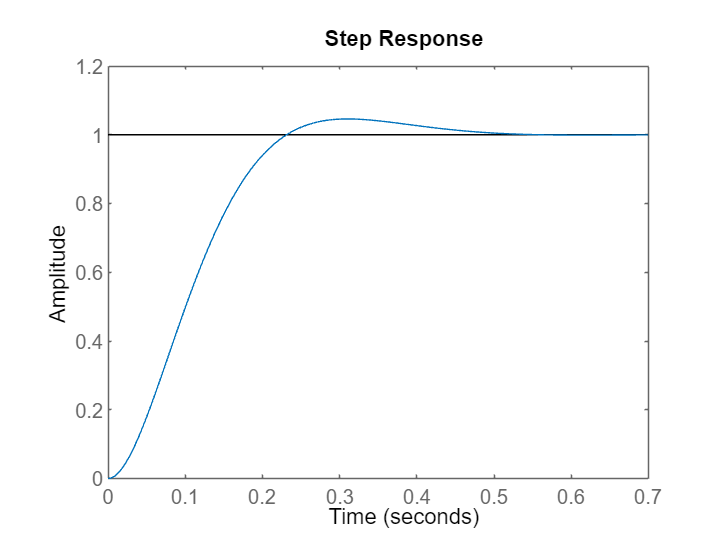

%OS of system response with step input: 4.60%


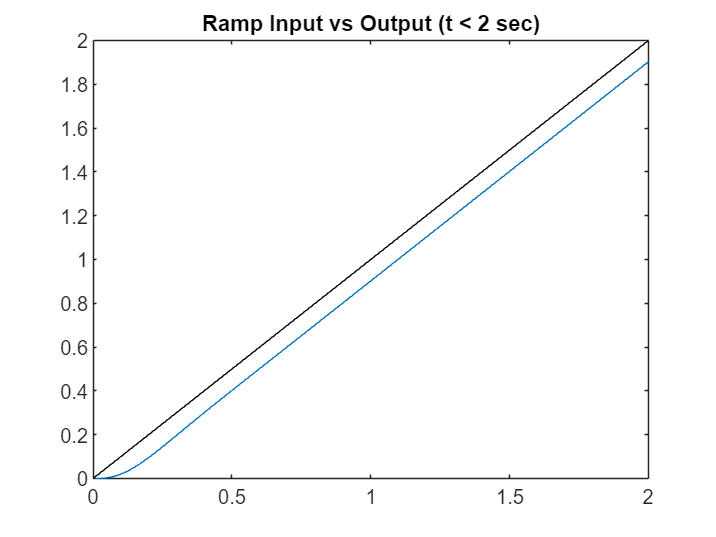

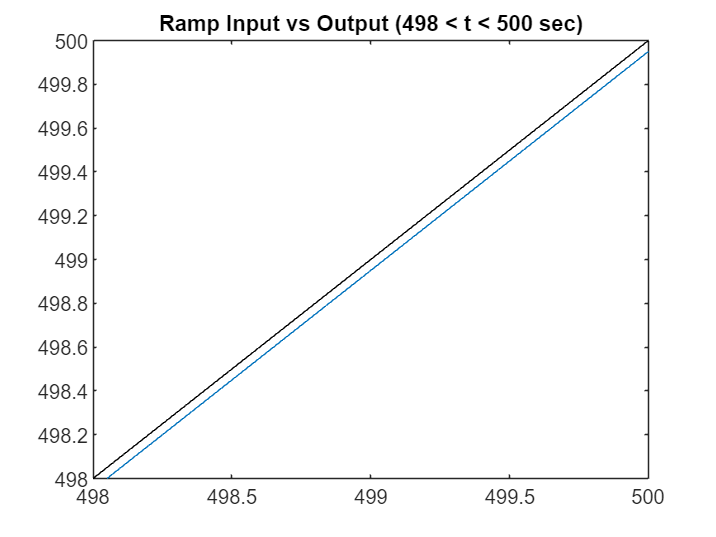

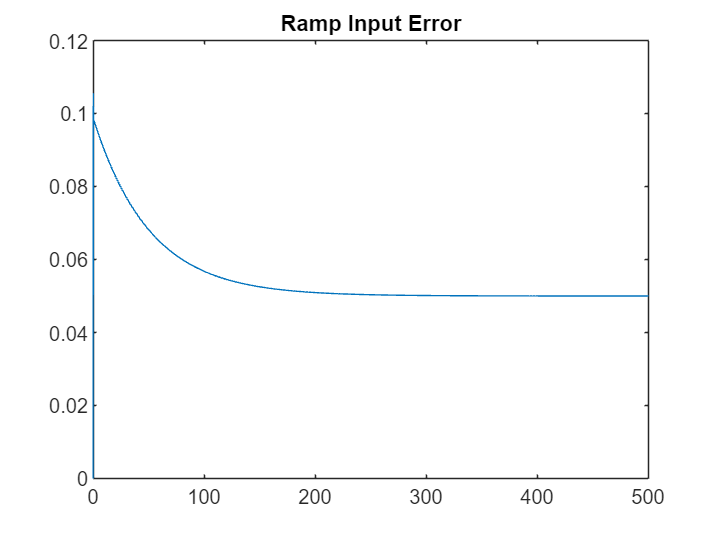

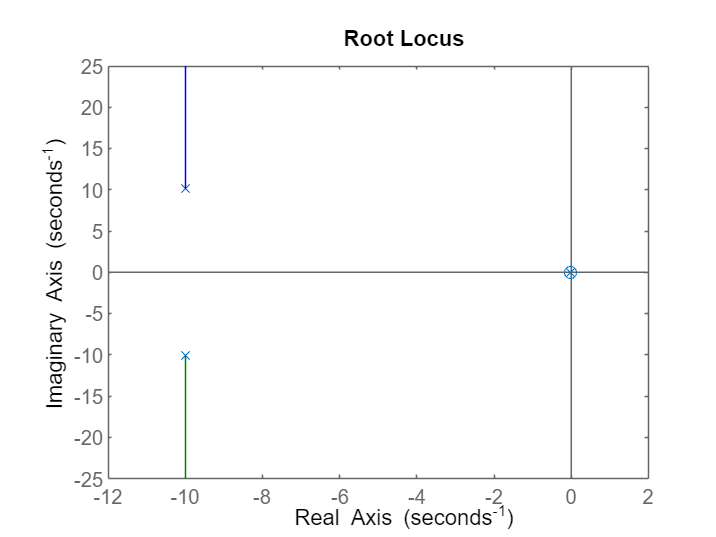


%               -------     ---     -----     ------
%       + _    | s + a |   |   |   |     |   | 500  |
%  R(s)--|_|---| ----- |---| K |---| 1/s |---| ---- |-------C(s)
%        -|    | s + b |   |   |   |     |   | s+20 |   |
%         |     -------     ---     -----     ------    |
%         |                                             |
%          ---------------------------------------------

verify_system(G_cl);

%OS of system response with step input: 4.60%



% convert system to discrete system
sigma = damping_ratio*nat_freq;
Ts = double((1/sigma)/10);  % find sampling time
discrete_G_ol = c2d(G_ol, Ts);  % convert open loop transfer function to z domain
discrete_G_cl = feedback(G_ol, 1);

verify_system(discrete_G_cl);



% verify system meets requirements
function verify_system(G_cl)
    % step input response
    figure;
    step(G_cl); 
    step_info = stepinfo(G_cl);
    percentage_OS = step_info.Overshoot;
    e_ss_step_input = 1 - dcgain(G_cl);
    fprintf('%%OS of system response with step input: %.2f%%\n', percentage_OS);
    
    % ramp input response
    t=0:0.001:500;    
    ramp_input = t.';
    unit_step = zpk([], [0], 1);
    G_cl_mod = G_cl*unit_step;
    [ramp_response, t1] = step(G_cl_mod, t);
    ramp_error = ramp_input - ramp_response;
    
    % plot ramp input results
    figure;
    idx = t <= 2;
    plot(t(idx), ramp_response(idx));
    hold on;
    plot(t(idx), ramp_input(idx), "Color", "Black");
    title("Ramp Input vs Output (t < 2 sec)");
    hold off;

    figure;
    idx = t >= 498;
    plot(t(idx), ramp_response(idx));
    hold on;
    plot(t(idx), ramp_input(idx), "Color", "Black");
    title("Ramp Input vs Output (498 < t < 500 sec)");
    ylim([498 500]);
    hold off;

    figure;
    plot(t, ramp_error);
    title("Ramp Input Error");
    
    % plot root locus
    figure;
    rlocus(G_cl);

    % return info
    sys_info = step_info;
end
